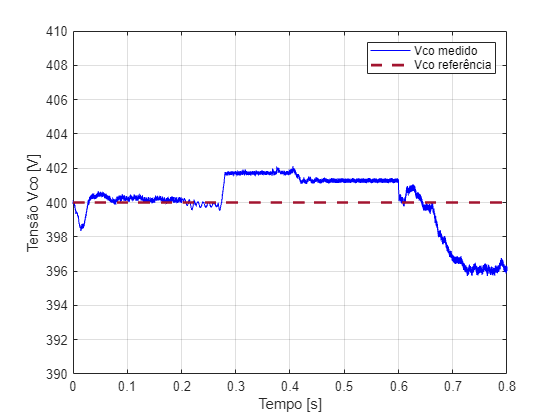

load("resultadoKalman.mat")


Vco = out.Vok.signals(1).values;
Vco_ref = out.Vok.signals(2).values;
ILs = out.ILsk.signals(1).values;
ILs_ref = out.ILsk.signals(2).values;
ILb = out.ILbk.signals(1).values;
ILb_ref = out.ILbk.signals(2).values;
t = linspace(0,0.8,length(Vco));

plot(t,Vco,"Color","b","DisplayName","Vco medido")
hold on
plot(t,Vco_ref,'--','LineWidth',2,"Color","#A2142F","DisplayName","Vco referência")
hold off
xlabel("Tempo [s]")
ylabel("Tensão Vco [V]")
axis([0 0.8 390 410])
legend
grid

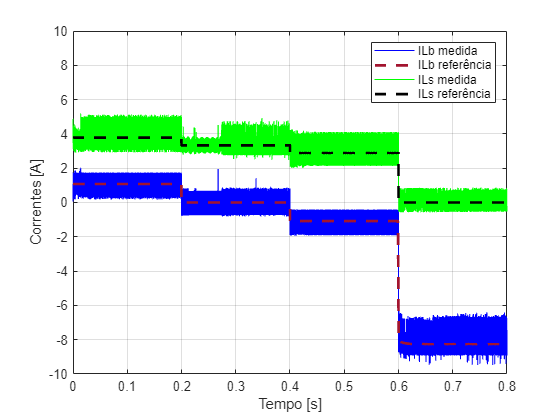


plot(t,ILb,"Color","b","DisplayName","ILb medida")
hold on
plot(t,ILb_ref,'--','LineWidth',2,"Color","#A2142F","DisplayName","ILb referência")
plot(t,ILs,"Color","g","DisplayName","ILs medida")
plot(t,ILs_ref,'--','LineWidth',2,"Color","#000000","DisplayName","ILs referência")
hold off
xlabel("Tempo [s]")
ylabel("Correntes [A]")
axis([0 0.8 -10 10])
legend
grid


m1 = Vco(1:20000);
m2 = Vco(20001:40000);
m3 = Vco(40001:60000);
m4 = Vco(60001:80000);
d1 = peak2peak(Vco(10000:20000));
d2 = peak2peak(Vco(30001:40000));
d3 = peak2peak(Vco(50001:60000));
d4 = peak2peak(Vco(70001:80000));

disp("REF  " + "Media     " + "EMRP  " + "   Delta ");

REF  Media     EMRP     Delta 


disp("400  " +mean(m1)+ "  "+ 100*(mean(m1) - 400)/400 + "  " + d1)

400  400.0862  0.02154  0.61546


disp("400  " +mean(m2)+ "  "+ 100*(mean(m2) - 400)/400 + "  " + d2)

400  401.0444  0.26111  0.57431


disp("400  " +mean(m3)+ "  "+ 100*(mean(m3) - 400)/400 + "  " + d3)

400  401.3354  0.33384  0.31139


disp("400  " +mean(m4)+ "  "+ 100*(mean(m4) - 400)/400 + "  " + d4)

400  397.8006  -0.54985  1.2296



m1 = ILb(1:20000);
m2 = ILb(20001:40000);
m3 = ILb(40001:60000);
m4 = ILb(60001:80000);
d1 = peak2peak(ILb(10000:20000));
d2 = peak2peak(ILb(30001:40000));
d3 = peak2peak(ILb(50001:60000));
d4 = peak2peak(ILb(70001:80000));

disp("REF  " + "Media     " + "EMRP  " + "   Delta ");

REF  Media     EMRP     Delta 


disp("1.08  " +mean(m1)+ "  "+ 100*(mean(m1) - 1.08)/1.08 + "  " + d1)

1.08  1.0531  -2.4901  1.5746


disp("0  " +mean(m2)+ "  "+ 100*(mean(m2) - 400)/400 + "  " + d2)

0  0.0088469  -99.9978  2.2259


disp("-1.08  " +mean(m3)+ "  "+ 100*(mean(m3) +1.08)/1.08 + "  " + d3)

-1.08  -1.1103  -2.8098  1.5035


disp("-8.03  " +mean(m4)+ "  "+ 100*(mean(m4) +8.03)/8.03 + "  " + d4)

-8.03  -7.9385  1.1397  3.0587



m1 = ILs(1:20000);
m2 = ILs(20001:40000);
m3 = ILs(40001:60000);
m4 = ILs(60001:80000);
d1 = peak2peak(ILs(10000:20000));
d2 = peak2peak(ILs(30001:40000));
d3 = peak2peak(ILs(50001:60000));
d4 = peak2peak(ILs(70001:80000));

disp("REF  " + "Media     " + "EMRP  " + "   Delta ");

REF  Media     EMRP     Delta 


disp("3.78  " +mean(m1)+ "  "+ 100*(mean(m1) - 3.78)/3.78 + "  " + d1)

3.78  3.7922  0.32317  2.2015


disp("3.33  " +mean(m2)+ "  "+ 100*(mean(m2) - 3.33)/3.33 + "  " + d2)

3.33  3.3673  1.1211  2.4283


disp("2.88  " +mean(m3)+ "  "+ 100*(mean(m3) - 2.88)/2.88 + "  " + d3)

2.88  2.9085  0.99099  1.9834


disp("0  " +mean(m4)+ "  "+ 100*(mean(m4) +8.03)/8.03 + "  " + d4)

0  0.070739  100.8809  1.406
